b = 10;     % damping co-efficient 
k = 400;    % spring constant
x0 = 1;     % initial condition 
m = 3;      % mass

md1 = gcs;
massValues = 1:2:11;
for i = 1:numel(massValues)
    m = massValues(i);
    results = sim(md1);
    
    plot(results.logsout.get("x").Values)
    hold on
    legendLabels{i} = "m=" + num2str(m);
    
    disp("Simulation " + num2str(i) + " complete")
end

Simulation 1 complete
Simulation 2 complete
Simulation 3 complete
Simulation 4 complete
Simulation 5 complete


Simulation 6 complete


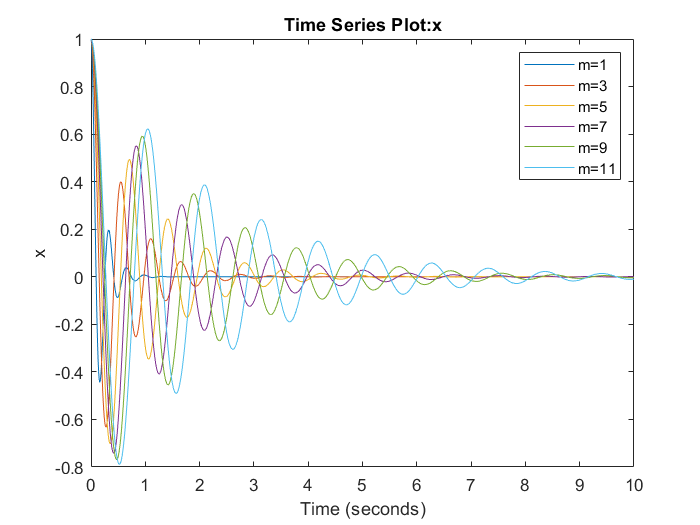

legend(legendLabels)